LandMark = [  13.2,9.21; -1.5,1.5; -1.5,-1.5;  5.01, -6.4]';
figure
axis ([-2 2 -8 10])
scatter(LandMark(1,:),LandMark(2,:),200, 'r','filled');
grid on
 
LandMark

LandMark =    13.2000   -1.5000   -1.5000    5.0100
    9.2100    1.5000   -1.5000   -6.4000



% Translate an rotate the Land Marks
alpha = pi/16 % Rotate pi/16 rad --> 22.5 degrees

alpha = 0.1963

tx = 0.1; % Translate 
ty = 0.2;
RotzTxy = [cos(alpha), sin(alpha), tx;...
       -sin(alpha), cos(alpha), ty;...
       0,           0,          1]

RotzTxy =     0.9808    0.1951    0.1000
   -0.1951    0.9808    0.2000
         0         0    1.0000


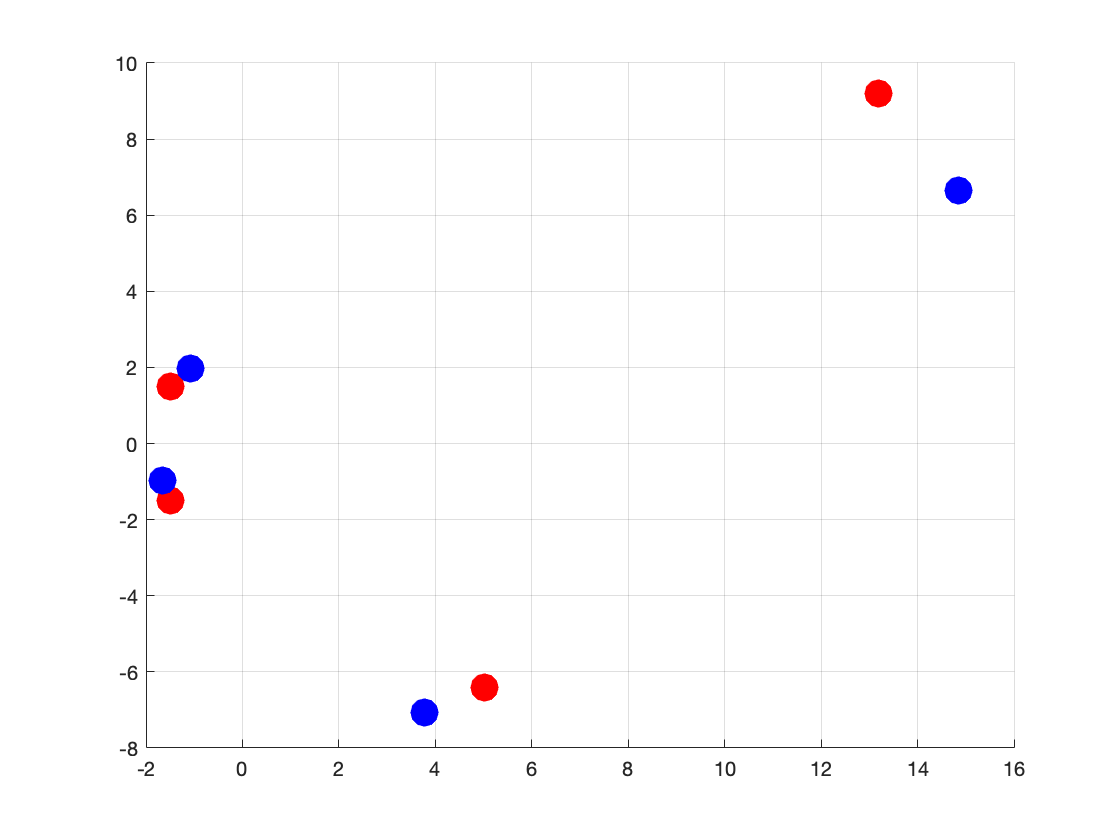

newLM = RotzTxy*[LandMark;ones(1,4)];
 
hold on;
scatter(newLM(1,:), newLM(2,:),200, 'b','filled');


%%%%%%

A = [];
for i=1:size(LandMark, 2)
    A = [A;[LandMark(1,i),LandMark(2,i),1,0]];
    A = [A;[LandMark(2,i),-LandMark(1,i),0,1]];
end
B = [];%Build Matrix B
for i=1:size(newLM, 2)
    B = [B; newLM(1,i); newLM(2,i)];
end
%Compute tx ty i tita
X = inv((A'*A))*A'*B;
tx_ST = X(3)

tx_ST = 0.1000

ty_ST = X(4)

ty_ST = 0.2000

alpha_ST = atan2(X(2),X(1))

alpha_ST = 0.1963